# Manuscript plots

Initial timeseries plot of NPP

Edit size to be longer in live script...

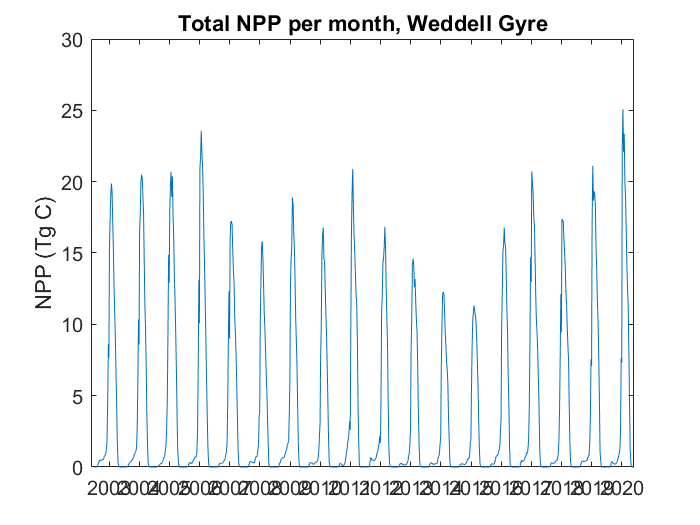

timedec_mid_npp=mean([timedec8day,timedec8day_end],2);
TotNPP_monthly=figure(1);
rix=1;
NPPmonth=plot(timedec_mid_npp,OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC);
ylabel('NPP (Tg C)');
title('Total NPP per month, Weddell Gyre');
set(gca,'XLim',[2002.4 2020.4], 'FontSize', 12);
xticks(2003:1:2020);

## Seasonal Cycles

### NPP

Time (x) variables for NPP

datenum_start=datenum(time_start_all);
datenum_end=datenum(time_end_all);
datenum_mid=mean([datenum_start,datenum_end],2);
datetime_mid=datetime(datenum_mid,'ConvertFrom','datenum');

datetime_aus=datetime_mid(1:46);

Plot NPP seasonal cycle

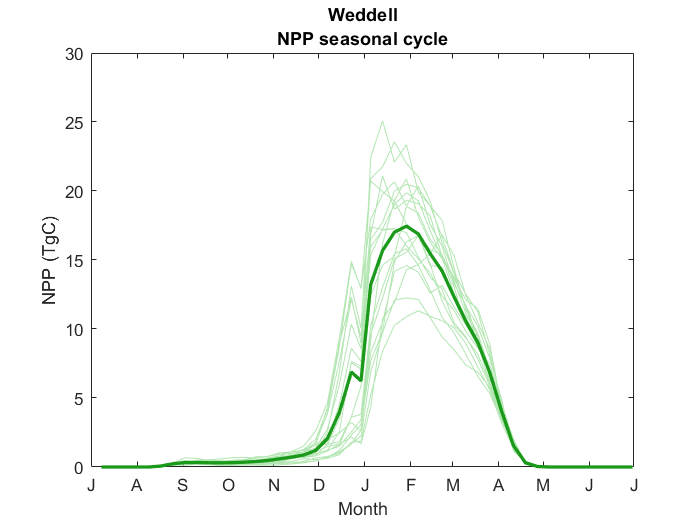

%close(MeanAusNPPtot)
MeanAusNPPtot=figure(2);
figure
NPPaus=plot(datetime_aus,OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC_cols, 'Color',[0.7 0.9 0.7]);
hold on
NPPmaus=plot(datetime_aus,OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC_mean,'Color',[0.1 0.6 0.1],'LineWidth',2);

xlim([datetime_aus(1) datetime_aus(46)])
datetick('x','m')
ylabel('NPP (TgC)')
xlabel('Month')
str=({region_sublist{rix};'NPP seasonal cycle'});
title(str)

### Sea Ice

Time (x) variables for Sea Ice 

SeaIce.Weddell.IFExtent_aus=SeaIce.g_area.Weddell-SeaIce.Weddell.SIExtent_aus;
SeaIce.Weddell.IFExtent_aus_mean=mean(SeaIce.Weddell.IFExtent_aus,2);

datenum_startice=datenum(time_start_allice);

datetime_ausice=datenum_startice(1:366);

Plot Ice-Free Extent seasonal cycle

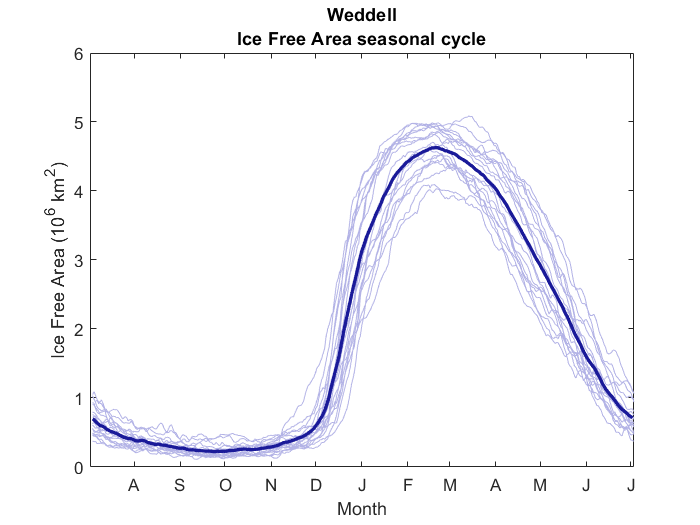

close(MeanAusSeaIce)
MeanAusSeaIce=figure(3);
IFEaus=plot(datetime_ausice,(SeaIce.Weddell.IFExtent_aus)/1e6, 'Color',[0.7 0.7 0.9]);
hold on
IFEmaus=plot(datetime_ausice,(SeaIce.Weddell.IFExtent_aus_mean)/1e6,'Color',[0.1 0.1 0.6],'LineWidth',2);
datetick('x','m')

xlim([datetime_ausice(1)-1.1 datetime_ausice(365)])
ylabel('Ice Free Area (10^6 km^2)')
xlabel('Month')
str=({region_sublist{rix};'Ice Free Extent seasonal cycle'});
title(str)

### Combine NPP and Sea Ice (Ice Free Extent) cycles

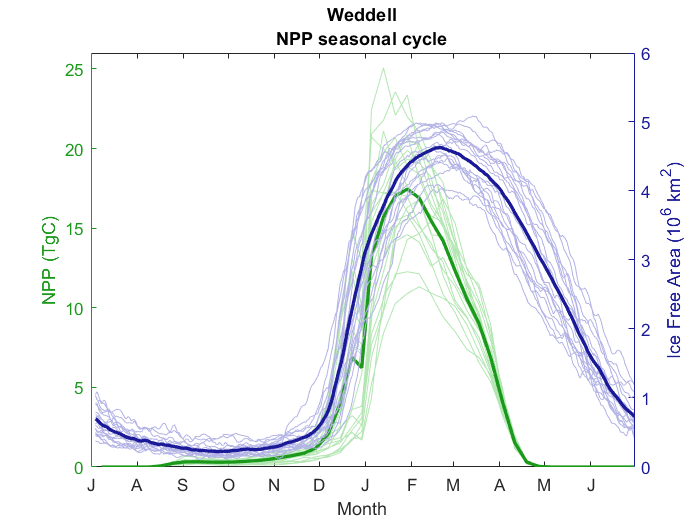

close(combinedAUS)
combinedAUS=figure(4);
left_color = [0.1 0.6 0.1];
right_color = [0.1 .1 .6];
set(combinedAUS,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
NPPaus=plot(datenum_mid(1:46),OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC_cols, ...
    'Color',[0.7 0.9 0.7],'LineStyle','-','Marker','none');
ylabel('NPP (TgC)')
ylim([0 26])
hold on
yyaxis right
IFEaus=plot(datenum_startice(1:366),(SeaIce.Weddell.IFExtent_aus)/1e6,...
    'Color',[0.7 0.7 0.9],'LineStyle','-','Marker','none');
ylabel('Ice Free Extent (10^6 km^2)')

yyaxis left
NPPmaus=plot(datenum_mid(1:46),OceanProd_8day.cafe.(region_sublist{rix}).NPP_tot_TgC_mean,...
    'Color',[0.1 0.6 0.1],'LineWidth',2,'LineStyle','-','Marker','none');
yyaxis right
IFEmaus=plot(datenum_startice(1:366),(SeaIce.Weddell.IFExtent_aus_mean)/1e6,...
    'Color',[0.1 0.1 0.6],'LineWidth',2,'LineStyle','-','Marker','none');
datetick('x','m')
xlim([datenum_startice(1)-3 datenum_startice(362)])
xlabel('Month')
str=({region_sublist{rix};'NPP seasonal cycle'});
title(str)